rng(0);
N = 40

N = 40

m = 50

m = 50

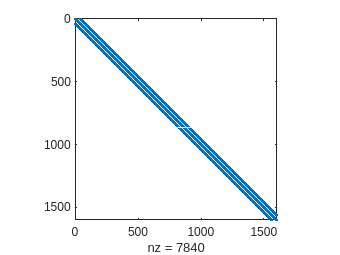

r = rand(N^2,1);
A = gallery('poisson',N);
spy(A)

[V, T] = lanczos(A, r, m)

V =     0.0357    0.0238   -0.0634    0.0189    0.0168    0.0386    0.0042   -0.0371   -0.0288    0.0152    0.0514   -0.0216   -0.0647    0.0166    0.0476    0.0011    0.0059    0.0027   -0.0328   -0.0181    0.0053    0.0028    0.0070    0.0048    0.0101    0.0050   -0.0067    0.0034   -0.0112   -0.0160    0.0103    0.0162    0.0122   -0.0020   -0.0177    0.0031   -0.0197   -0.0135    0.0376    0.0131   -0.0084   -0.0075   -0.0065   -0.0005    0.0190   -0.0067   -0.0441    0.0044    0.0444    0.0176
    0.0397    0.0303   -0.0195    0.0375   -0.0637   -0.0287   -0.0004    0.0342    0.0367   -0.0298   -0.0123    0.0118    0.0165    0.0269   -0.0166   -0.0575   -0.0087    0.0280    0.0199    0.0336    0.0157   -0.0349   -0.0116    0.0124   -0.0081   -0.0226   -0.0035    0.0226    0.0079    0.0049    0.0056   -0.0291   -0.0242    0.0175    0.0133    0.0177   -0.0110    0.0023    0.0266   -0.0356   -0.0147    0.0075   -0.0007   -0.0066    0.0185    0.0284   -0.0012   -0.0046   -0.0236   -0

H =     1.0412    1.9618         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9618    4.7524    1.7765         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

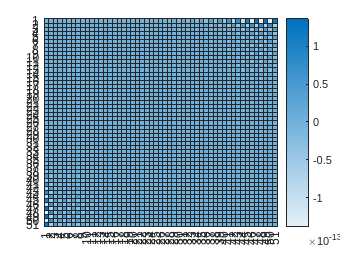

heatmap(V' * V - eye(m+1))

[V, H] = arnoldi(A, r, m)

V =     0.0357    0.0238   -0.0634    0.0189    0.0168    0.0386    0.0042   -0.0371   -0.0288    0.0152    0.0514   -0.0216   -0.0647    0.0166    0.0476    0.0011    0.0059    0.0027   -0.0328   -0.0181    0.0053    0.0028    0.0070    0.0048    0.0101    0.0050   -0.0067    0.0034   -0.0112   -0.0160    0.0103    0.0162    0.0122   -0.0020   -0.0177    0.0031   -0.0197   -0.0135    0.0376    0.0131   -0.0084   -0.0075   -0.0065   -0.0005    0.0190   -0.0067   -0.0441    0.0044    0.0444    0.0176
    0.0397    0.0303   -0.0195    0.0375   -0.0637   -0.0287   -0.0004    0.0342    0.0367   -0.0298   -0.0123    0.0118    0.0165    0.0269   -0.0166   -0.0575   -0.0087    0.0280    0.0199    0.0336    0.0157   -0.0349   -0.0116    0.0124   -0.0081   -0.0226   -0.0035    0.0226    0.0079    0.0049    0.0056   -0.0291   -0.0242    0.0175    0.0133    0.0177   -0.0110    0.0023    0.0266   -0.0356   -0.0147    0.0075   -0.0007   -0.0066    0.0185    0.0284   -0.0012   -0.0046   -0.0236   -0

H =     1.0412    1.9618   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.9618    4.7524    1.7765    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0

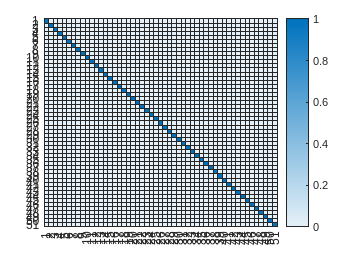

heatmap(V' * V)

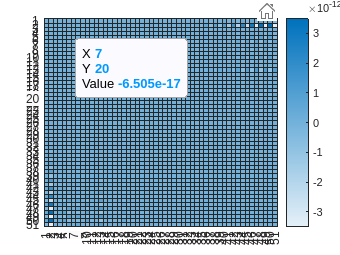

heatmap(V' * V - eye(m+1))

B = konv_diff(N,1e-10);
[V, H] = arnoldi(B, r, m);
heatmap(V' * V)

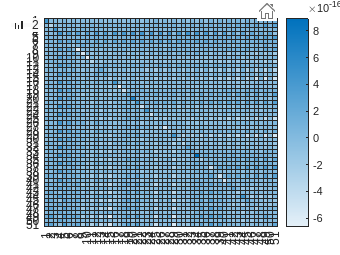

heatmap(V' * V - eye(m+1))

[V, H] = arnoldi_RE(A, r, m);
heatmap(V' * V)

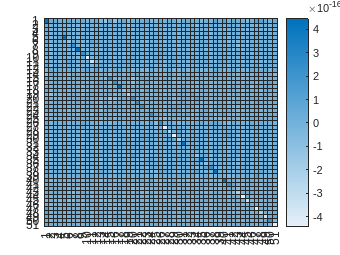

heatmap(V' * V - eye(m+1))

c = -1 +sqrt(5) * 1i;
Atilde = A + c * eye(size(A));
[Va, H] = arnoldi(Atilde, r, m)

Va =    0.0357 + 0.0000i   0.0096 + 0.0327i  -0.0141 + 0.0152i  -0.0248 - 0.0155i   0.0552 - 0.0003i  -0.0103 + 0.0511i  -0.0031 + 0.0019i  -0.0045 + 0.0063i   0.0206 - 0.0203i   0.0311 + 0.0271i  -0.0058 + 0.0369i  -0.0284 + 0.0046i  -0.0023 - 0.0172i   0.0211 + 0.0011i   0.0048 + 0.0347i  -0.0358 + 0.0155i  -0.0281 - 0.0329i   0.0362 - 0.0220i   0.0008 + 0.0446i  -0.0490 + 0.0015i  -0.0196 - 0.0461i   0.0362 - 0.0198i   0.0026 + 0.0161i  -0.0111 - 0.0017i  -0.0064 - 0.0058i  -0.0041 - 0.0076i  -0.0021 - 0.0243i   0.0257 - 0.0086i   0.0105 + 0.0169i  -0.0156 + 0.0077i  -0.0054 - 0.0160i   0.0097 - 0.0081i   0.0107 - 0.0061i   0.0089 + 0.0038i   0.0102 + 0.0044i  -0.0031 + 0.0068i   0.0060 - 0.0029i   0.0019 + 0.0004i   0.0170 - 0.0021i   0.0052 + 0.0114i   0.0136 + 0.0038i   0.0036 + 0.0104i   0.0130 + 0.0192i  -0.0136 + 0.0107i   0.0148 + 0.0022i   0.0053 + 0.0151i   0.0098 + 0.0311i  -0.0222 + 0.0172i  -0.0101 + 0.0151i  -0.0135 - 0.0051i
   0.0397 + 0.0000i   0.0122 + 0.0363i  -0.0

H =    0.0412 - 2.2361i  -1.2596 - 0.0377i   0.9936 - 1.0773i  -1.8157 - 0.6714i  -0.1121 + 0.1726i  -0.3134 - 0.1239i  -0.1536 + 0.0076i  -0.1251 + 0.0024i  -0.0550 + 0.0080i  -0.0564 + 0.0042i  -0.0385 + 0.0011i  -0.0288 + 0.0090i  -0.0218 + 0.0004i  -0.0156 + 0.0072i  -0.0148 + 0.0001i  -0.0079 + 0.0066i  -0.0076 + 0.0001i  -0.0039 + 0.0041i  -0.0050 + 0.0003i  -0.0018 + 0.0031i  -0.0029 + 0.0002i  -0.0008 + 0.0021i  -0.0015 + 0.0003i  -0.0001 + 0.0013i  -0.0009 + 0.0001i   0.0001 + 0.0009i  -0.0005 + 0.0002i   0.0003 + 0.0006i  -0.0002 + 0.0001i   0.0002 + 0.0003i  -0.0000 + 0.0001i   0.0002 + 0.0002i   0.0001 + 0.0001i   0.0002 + 0.0001i   0.0001 + 0.0000i   0.0002 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 - 0.0000i   0.0001 + 0.0000i   0.0001 - 0.0000i   0.0001 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i
   4.8835 + 0.0000i   0.6746 - 1.0826i   1.63

[Vl, T] = lanczos(Atilde, r, m)

Vl =    0.0357 + 0.0000i   0.0096 + 0.0327i  -0.0336 + 0.0080i  -0.0099 - 0.0328i   0.0329 - 0.0095i   0.0100 + 0.0327i  -0.0328 + 0.0099i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i  -0.0327 + 0.0100i  -0.0100 - 0.0327i   0.0327 - 0.0100i   0.0100 + 0.0327i
   0.0397 + 0.0000i   0.0122 + 0.0363i  -0.0

T = 1.0e+15 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.0